clearvars
data = load("failure_times_1.mat")

data = struct with fields:
    ft: [1.1999e+04 1.1980e+04 1.1999e+04 7.4582e+03 344.8291 1.0705e+04 974.4007 5.8609e+03 1.2000e+04 1.1989e+04 5.5599e+03 5.4614e+03 312.9325 1.2000e+04 6.6671e+03 1.1945e+04 1.1946e+04 1.2000e+04 1.2000e+04 1.1943e+04 1.0367e+04 1.0227e+04 … ]



n = length(data.ft)

n = 25

sorted_data = sort(data.ft)

sorted_data = 1.0e+04 *

    0.0313    0.0345    0.0974    0.5461    0.5560    0.5861    0.6667    0.7161    0.7458    1.0227    1.0367    1.0705    1.1171    1.1943    1.1945    1.1946    1.1946    1.1980    1.1989    1.1999    1.1999    1.2000    1.2000    1.2000    1.2000


min_ft = min(data.ft)

min_ft = 312.9325

max_ft = max(data.ft)

max_ft = 1.2000e+04

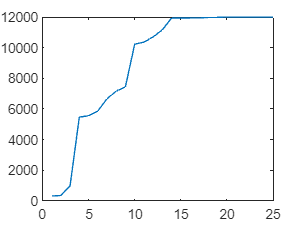


plot(1:25, sorted_data)


w = max_ft - min_ft;
m = round(sqrt(n));
omega = w / (m-1);
u = [];
u(1) = min_ft - omega/2;
rc = 9;
tc = 7458;
tt = 11000;
rt = 12;

i = 2;
while i <= n 
    u(i) = u(i - 1) + omega;
    i = i + 1;
end
u_first_set = u(1:5);
u_second_set = u(6:10);
u_third_set = u(11:15);
u_fourth_set = u(16:20);
u_fifth_set = u(20:25);

SE = sum(sorted_data)

SE = 2.2602e+05

SC = sum(sorted_data(1:rc))+(min_ft-rc)*tc

SC = 2.3065e+06

ST = sum(sorted_data(1:rt))+(min_ft-rc)*tt

ST = 3.4144e+06


SE/sorted_data(1)

ans = 722.2512


u(3)

ans = 4.6956e+03

u(7)

ans = 1.6383e+04

u(13)

ans = 3.3913e+04

u(17)

ans = 4.5600e+04

u(23)

ans = 6.3131e+04


rtci_1 = u(3)/sorted_data(1)

rtci_1 = 15.0051

rtci_2 = u(7)/sorted_data(1)

rtci_2 = 52.3520

rtci_3 = u(13)/sorted_data(1)

rtci_3 = 108.3724

rtci_4 = u(17)/sorted_data(1)

rtci_4 = 145.7193

rtci_5 = u(23)/sorted_data(1)

rtci_5 = 201.7397


% lambda1 = 
lambda2 = /u(3)/(tmax - tmin)/(m - 1)
lambda3 = /u(7)/
lambda4 = /u(13)/
lambda5 = /u(17)/

% mtbf_t = ST/(r + 1)